% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 80e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 1;

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                 % 脉冲个数
PRI = 200e-6;            % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴

% === 构造发射信号 ===
tx = zeros(1, N_total);
target_start_idx_in_PRI = 5e3

target_start_idx_in_PRI = 5000

for k = 0:Np-1
    start_idx = k * PRI_samp + target_start_idx_in_PRI;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 15;
Bj = 5e6;  % 扫频带宽
fjc = 0;   % 干扰中心频率
data_num = 3 %干扰样本数

data_num = 3

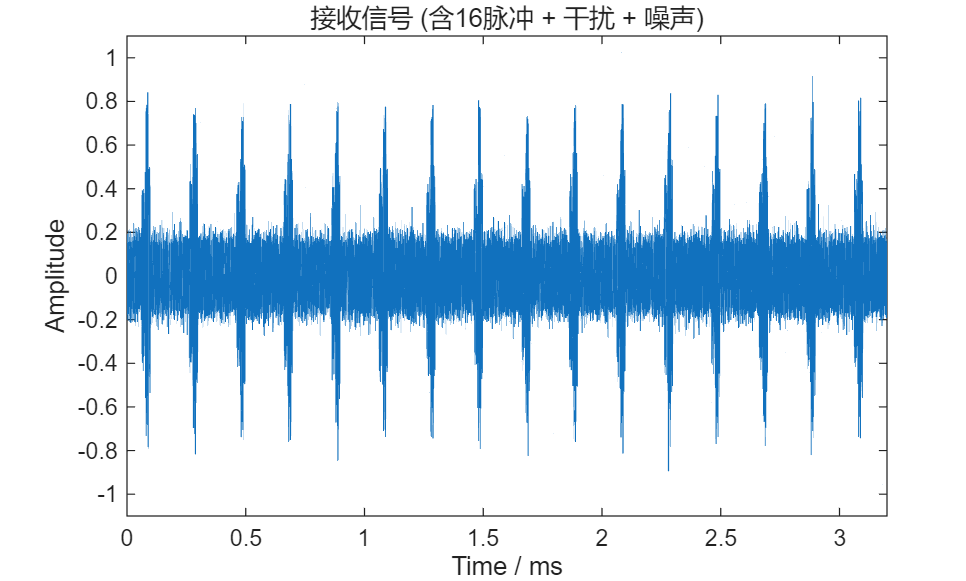

As = 10^(SNR/20);
Aj = 10^(JNR/20);

jam = zeros(data_num,N_total);

for m = 1:data_num
    % 生成高斯白噪声
    sp = randn([1,N_total]) + 1j*randn([1,N_total]);
    sp = sp / std(sp);
    white_noise = sp;

    % ======================================================================
    % === 生成密集假目标干扰 (Dense False Target Jamming - DFTJ) ===
    % 这是您要求修改的核心部分
    % ======================================================================

    % --- 1. 设置假目标参数 ---
    k = 4;%+randi([3, 6]);  % 随机产生3-6个假目标

    % --- 2. 创建一个PRI长度的干扰信号模板 ---
    % 我们首先在一个PRI内生成假目标，然后将其复制到所有PRI
    jam_pri = zeros(1, PRI_samp);

    % --- 3. 循环生成每个假目标并放入模板 ---
    for i = 1:k
        % 随机延迟时间 (1-10us)，并转换为采样点数
        delay_time = (1 + rand() * 9) * 1e-6;
        delay_samp = round(delay_time * fs);
        if i == 1
            % 第一个假目标相对于真实目标的位置
            left_range = target_start_idx_in_PRI + delay_samp*(m+i-1);
        else
            % 后续假目标相对于前一个假目标的位置
            left_range = last_pos + delay_samp;
        end
        right_range = left_range + Ntau - 1;

        % 记录当前假目标的位置，供下一个假目标参考
        last_pos = left_range;

        % 检查假目标是否超出当前PRI的范围，如果超出则不添加
        if right_range <= PRI_samp
            % 为每个假目标设置一个随机幅度 (0.5到1.5倍的Aj)
            Aj_rand = Aj * (0.5 + rand());
            jam_pri(left_range:right_range) = jam_pri(left_range:right_range) + Aj_rand * lfm;
        end
    end

    % --- 4. 将单个PRI的干扰模板复制到整个信号长度 ---
    jam_signal = repmat(jam_pri, 1, Np)+sp;
    

    % --- 5. 保存生成的干扰样本 ---
    jam(m, :) = jam_signal;

end

% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
pure_echo = As*tx;
rx = As*tx + jam_signal + white_noise;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');

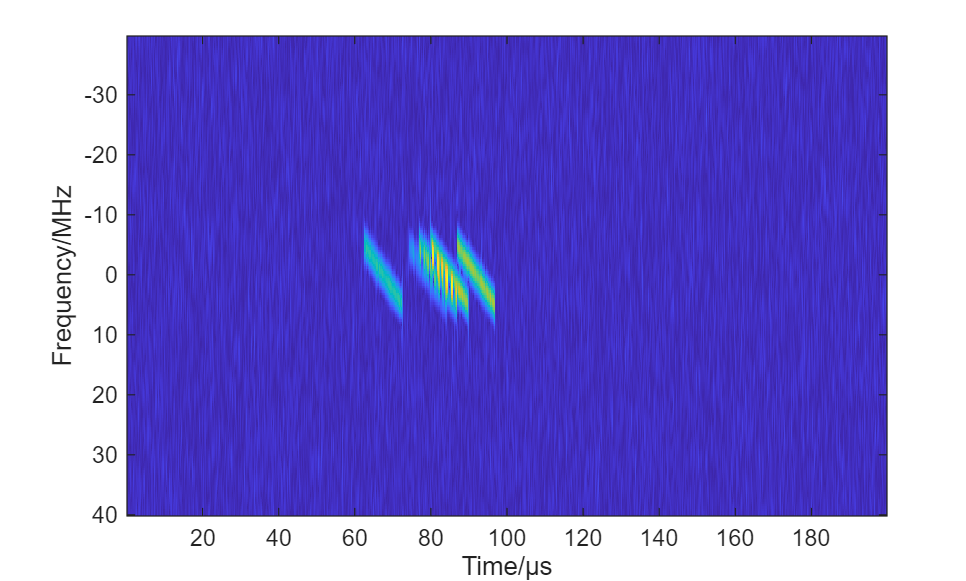



figure;
[S,F,T] = spectrogram(rx(1:PRI_samp),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);


